## 6.2.2

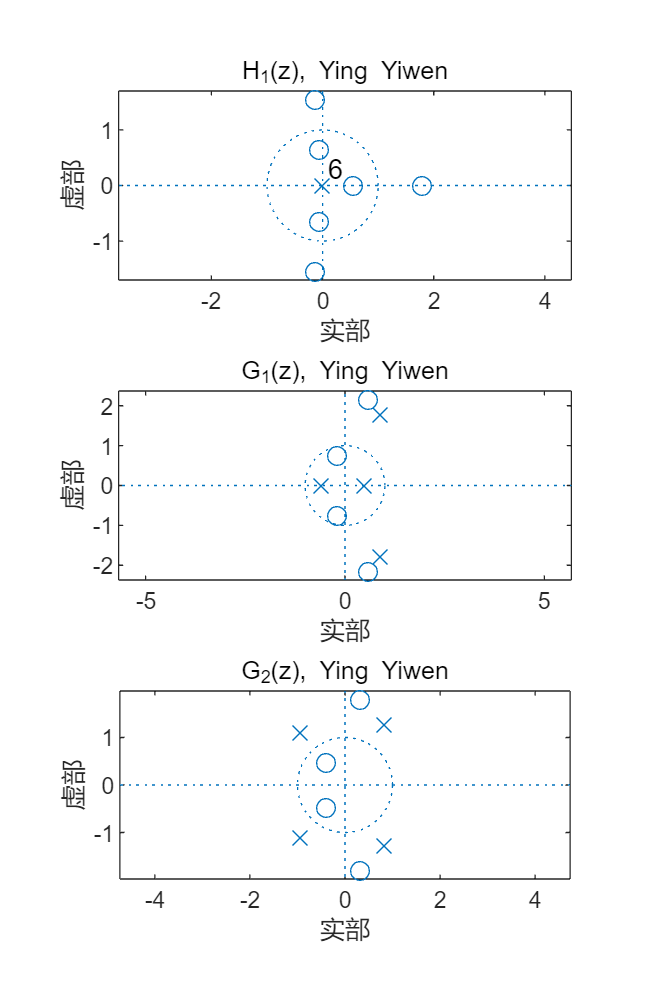

clear;
P1 = [-1 2 -3 6 -3 2 -1];
D1 = [1 zeros(1,6)];
P2 = [3 -2.4 15.36 3.84 9];
D2 = [5 -8.5 17.6 4.7 -6];
P3 = [2 0.2 6.4 4.6 2.4];
D3 = [5 1 6.6 4.2 24];
zeros1 = roots(P1);
poles1 = roots(D1);
zeros2 = roots(P2);
poles2 = roots(D2);
zeros3 = roots(P3);
poles3 = roots(D3);
figure('Position', [100, 100, 800, 1200]);
subplot(3,1,1),zplane(zeros1,poles1),title('H_1(z), Ying Yiwen');
subplot(3,1,2),zplane(zeros2,poles2),title('G_1(z), Ying Yiwen');
subplot(3,1,3),zplane(zeros3,poles3),title('G_2(z), Ying Yiwen');

H1, ROC outside the outermost pole, right sequence

G1, ROC between the poles, two-sided sequence

G2, ROC inside the innermost pole, left sequence

## 6.2.3

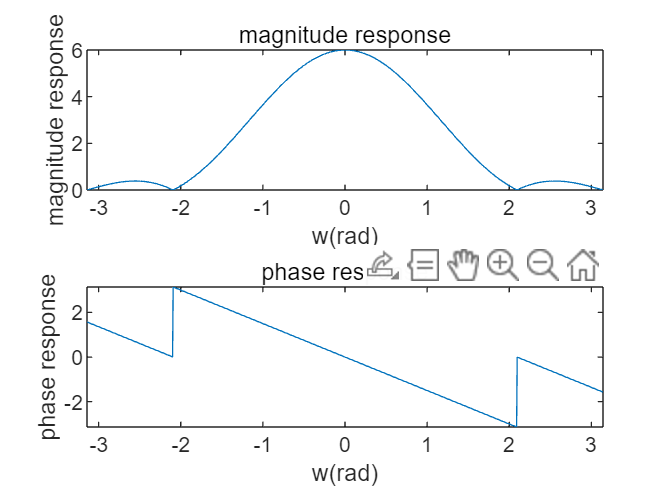

P1 = [1 2 2 1];
D1 = [1 zeros(1,3)];
P2 = [1 0 -1];
D2 = [1 -1.2 0.95];
[mag1, phase1] = FreRes(P1, D1);

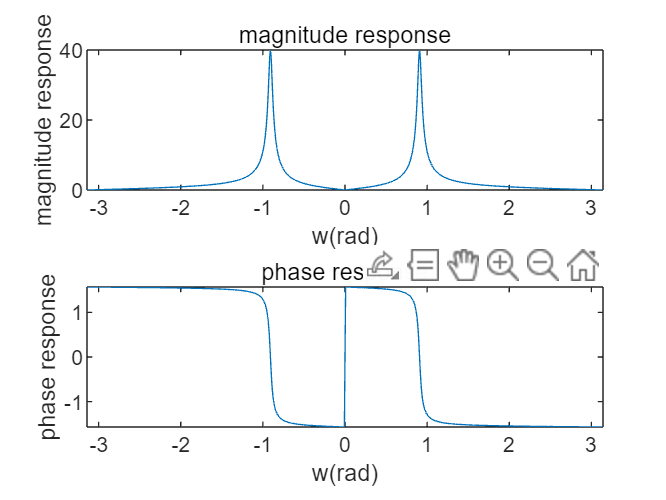

[mag2, phase2] = FreRes(P2, D2);

## 6.2.4

[p, d, k] = residue([-7.8 3], [-1.12 0.9 1]);
-p./d

ans =    -2.4783
    5.4783


1./d

ans =     0.7000
   -1.6000


k


k =

     []



Right-Sided Sequence: ROC={z:|z|>1.6}. x[n]=-2.4783(0.7)^n*u[n]+5.4783(-1.6)^n*u[n].

Left-Sided Sequence: ROC={z:|z|<0.7}. x[n]=2.4783(0.7)^n*u[-n-1]-5.4783(-1.6)^n*u[-n-1].

Two-Sided Sequence: ROC={z:0.7<|z|<1.6}. x[n]=-2.4783(0.7)^n*u[n]-5.4783(-1.6)^n*u[-n-1].

[p, d, k] = residue([1.28 1.8 3],[-0.2 -0.1 1]);
-p./d

ans =     2.8889
    6.5111


1./d

ans =    -0.4000
    0.5000


k

k = -6.4000

Right-Sided Sequence: ROC={z:|z|>0.5}. x[n]=2.8889(-0.4)^n*u[n]+6.5111(0.5)^n*u[n]-6.4000delta[n].

Left-Sided Sequence: ROC={z:|z|<0.4}. x[n]=-2.8889(-0.4)^n*u[-n-1]-6.5111(0.5)^n*u[-n-1]-6.4000delta[n].

Two-Sided Sequence: ROC={z:0.4<|z|<0.5}. x[n]=2.8889(-0.4)^n*u[n]-6.5111(0.5)^n*u[-n-1]-6.4000delta[n].

## 6.2.5

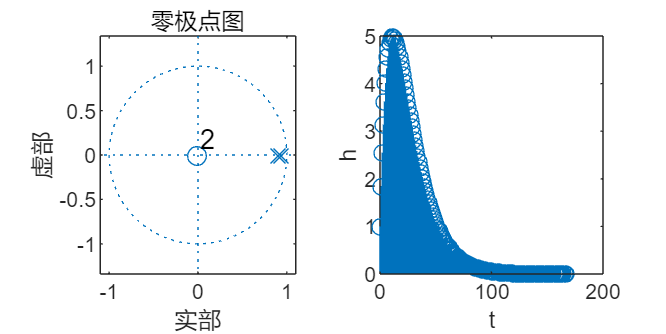

poles1 = [0.943 0.902];
zeros1 = [0 0];
b1 = 1;
a1 = [1 -1.845 0.850586];
[h1,t1] = impz(b1,a1);

poles2 = [1 0.85];
zeros2 = [0 0];
b2 = 1;
a2 = [1 -1.85 0.85];
[h2,t2] = impz(b2,a2);

figure('Position', [100, 100, 800, 400]);
subplot(121), zplane(zeros1',poles1');
subplot(122), stem(t1,h1), xlabel('t'), ylabel('h');

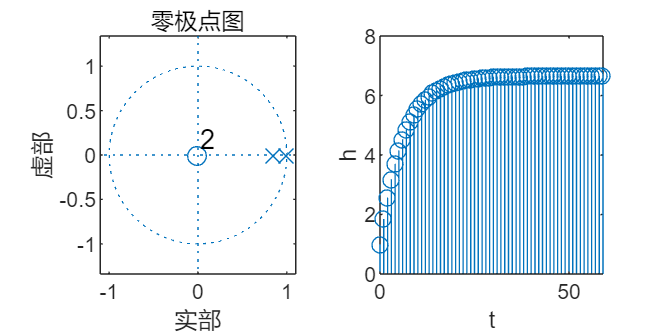

figure('Position', [100, 100, 800, 400]);
subplot(121), zplane(zeros2',poles2');
subplot(122), stem(t2,h2), xlabel('t'), ylabel('h');

H1幅值更小，更稳定

H2有极点在ROC上，更不稳定

## 6.3.1

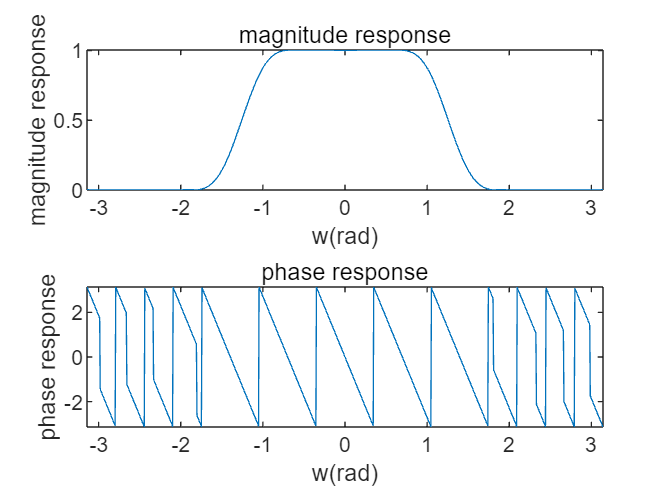

clc,clear,close all;
h=[-0.0035,-0.0039,0.0072,0.0201,-0.0000,-0.0517,-0.0506,0.0855,0.2965,0.4008,0.2965,0.0855,-0.0506,-0.0517,-0.0000,0.0201,0.0072,-0.0039,-0.0035];
[mag,phase]=FreRes(h,1);

幅度特性，低通滤波器

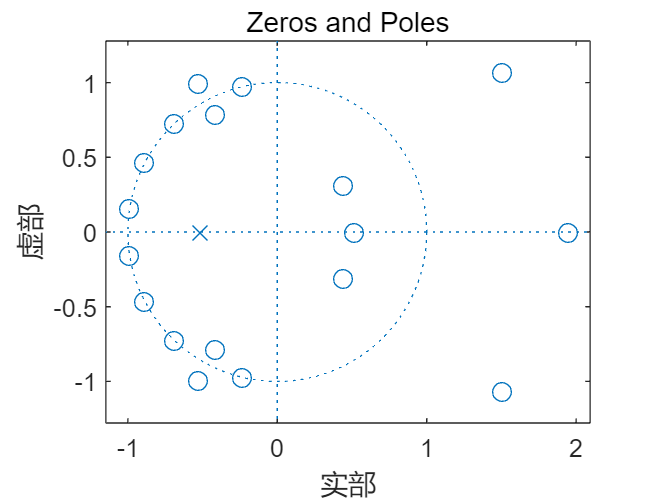

zeros = roots(h);
poles = roots([1 zeros(18,1)]);
figure;
zplane(zeros, poles),title('Zeros and Poles');

第三种滤波器，z=1,z=-1为零点，无法成为低通滤波（低频必须不为零）

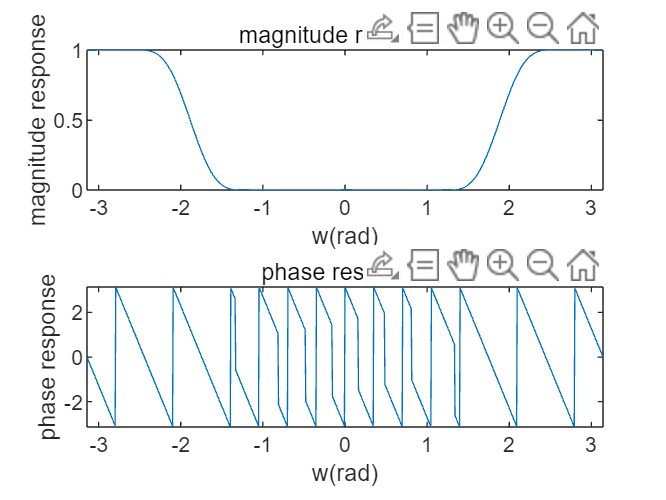

clear zeros;
h1 = h;
h1(2:2:19) = -h1(2:2:19);
h2 = zeros(1,91);
h2(1:5:91) = h(1:1:19);
[mag1,phase1] = FreRes(h1,1);

H1, 频移

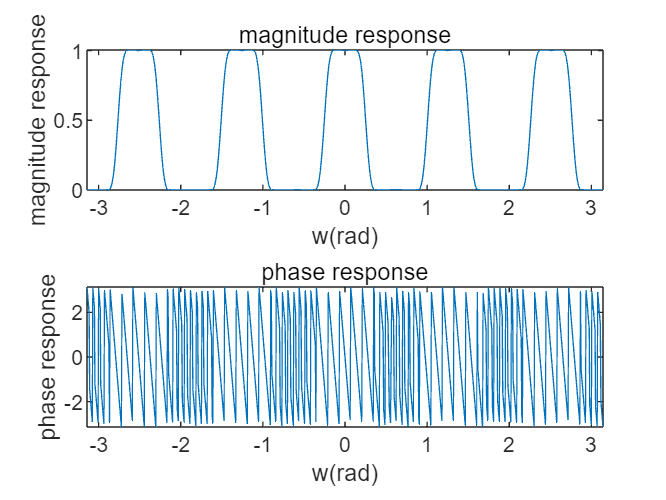

[mag2,phase2] = FreRes(h2,1);

H2，scaling

## 6.3.2

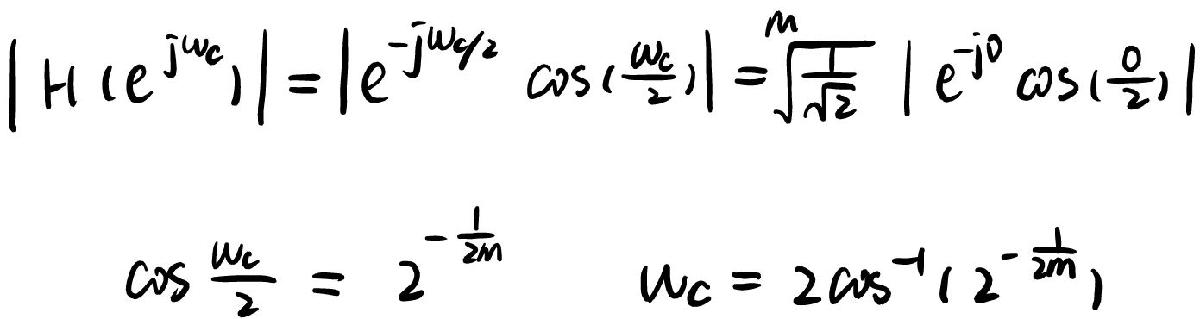

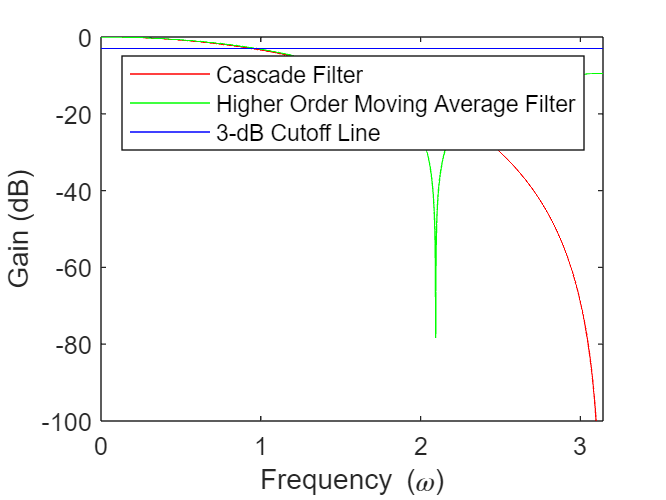

clc,clear,close all;
w = linspace(0, pi, 5000);
H_cascade = exp(-1i * 3 * w / 2) .* (cos(w / 2)).^3;
M = 3;
H_moving_average = (1/M) * sin(M .* w / 2) ./ sin(w / 2) .* exp(-1j * (M-1) .* w / 2);

figure;
plot(w, 20 * log10(abs(H_cascade)),'r');
hold on;
plot(w, 20 * log10(abs(H_moving_average)),'g');
plot(w, -3 * ones(1, 5000),'b');
ylim([-100, 0]);
xlabel('Frequency (\omega)'),ylabel('Gain (dB)'),legend('Cascade Filter', 'Higher Order Moving Average Filter', '3-dB Cutoff Line');

Try M, when M=3, they have same amplitude at 3db

## 6.4

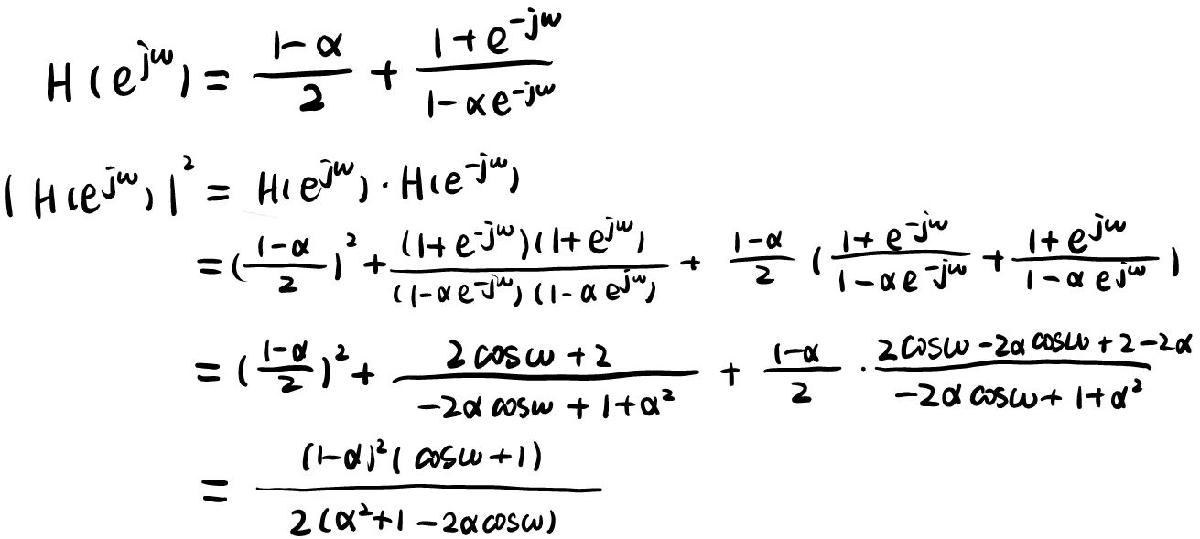

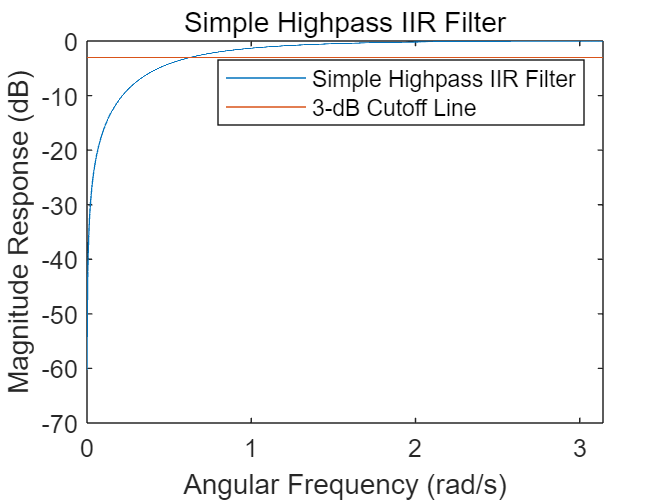

clc,clear,close all;
alpha_hpf = (1 - sqrt(1 - cos(0.2 * pi)^2)) / cos(0.2 * pi);
w = linspace(0, pi, 5000);
H = sqrt(((1 + alpha_hpf)^2 * (1 - cos(w))) ./ (2 * (1 + alpha_hpf^2 - 2 * alpha_hpf * cos(w))));
figure;
plot(w, 20 * log10(abs(H)));
hold on;
plot(w, -3 * ones(1, 5000));
xlabel('Angular Frequency (rad/s)'),ylabel('Magnitude Response (dB)'),title('Simple Highpass IIR Filter');
legend('Simple Highpass IIR Filter', '3-dB Cutoff Line');

-3db at 0.2pi, it's highpass filter

function [mag, phase] = FreRes(num, den)
    % num 分子
    % den 分母
    nP = 0:-1:1-length(num);
    nD = 0:-1:1-length(den);
    syms w;
    P = sum(num .* exp(1i * w).^nP, 2); % true num
    D = sum(den .* exp(1i * w).^nD, 2); % true den
    H = P ./ D;
    mag = abs(H);
    phase = angle(H);
    
    figure;
    subplot(2,1,1), fplot(w, mag, [-pi, pi]);
    xlabel('w(rad)'), ylabel('magnitude response');
    title('magnitude response');
    subplot(2,1,2), fplot(w, phase, [-pi, pi]);
    xlabel('w(rad)'), ylabel('phase response');
    title('phase response');
end
